# Ex 2 - Distributed Optimization

clear variables
close all
clc

run_admm = false;

## Rng seed

rng(1)

## Initialization

#### Distributed network

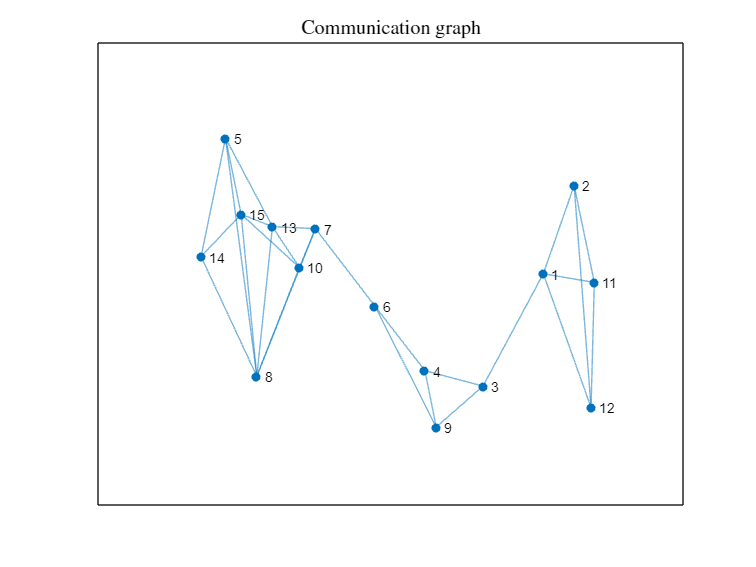

N = 15;                         % number of nodes
r = 0.2;                        % radius of random graph

[A,L] = random_graph(N,r,true); % generate random graph

d_vec = sum(A,1);
D = diag(d_vec);

#### Consensus matrix

P = zeros(N);

for i = 1:N
    for j = find(A(i,:))        % iterate over i's neighbors
        
        P(i,j) = 1/(1+max(d_vec(i), d_vec(j)));
        
    end
    
    P(i,i) = 1-sum(P(i,:));     % diagonal element
end

#### Costs function

% local cost functions parameters
a = rand(N, 1) * 0.2;
b = rand(N, 1) * 0.2;
c = rand(N, 1);
d = rand(N, 1);

% cost function
f = @(x) cost_function(x, a, b, c, d);

#### Random initial conditions

x0 = randn(N,1);

#### Optimal value

https://nl.mathworks.com/help/optim/ug/passing-extra-parameters.html

[x_opt, fval] = fmincon(f, mean(x0));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Cost function plot

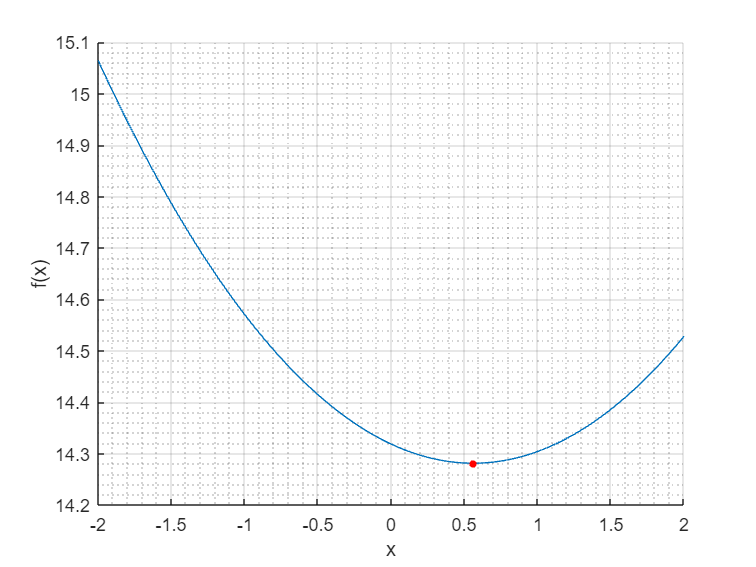

% plot
x_plot = -2:0.01:2;
f_plot = f(x_plot);
figure()
    hold on
    plot(x_plot, f_plot)
    plot(x_opt, fval, 'r.', 'MarkerSize', 12)
    grid on
    grid minor
    xlabel('x')
    ylabel('f(x)')

## DGD

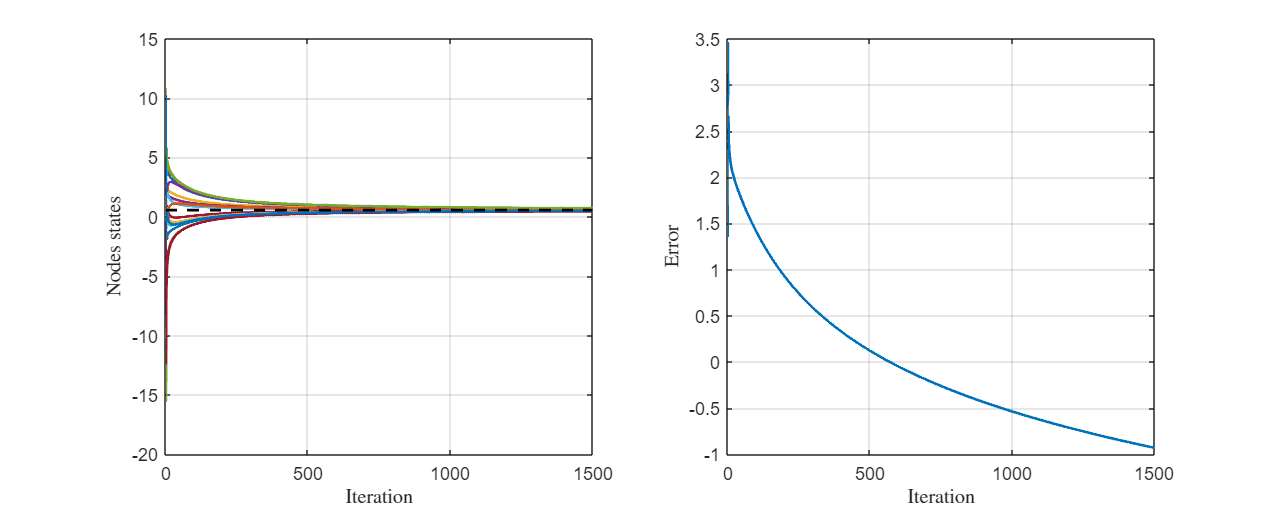

sim_len = 1500; % simulations length
    
X = [x0, zeros(N,sim_len)]; % initialize nodes states
eps = 0.01;

for k = 1:sim_len
        
    grad = a.*c.*exp(a.*X(:,k)) - b.*d.*exp(-b.*X(:,k));
    X(:,k+1) = P*X(:,k) - (1/(eps*k))*(grad);

end

% compute final x and f values
x_dgd = mean(X(:, end));
fval_dgd = f(x_dgd);

% plot result
plot_results(X, x_opt)

## Newton-Raphson

Exploits second order derivative in the state update. The epsilon variable represents the step size.

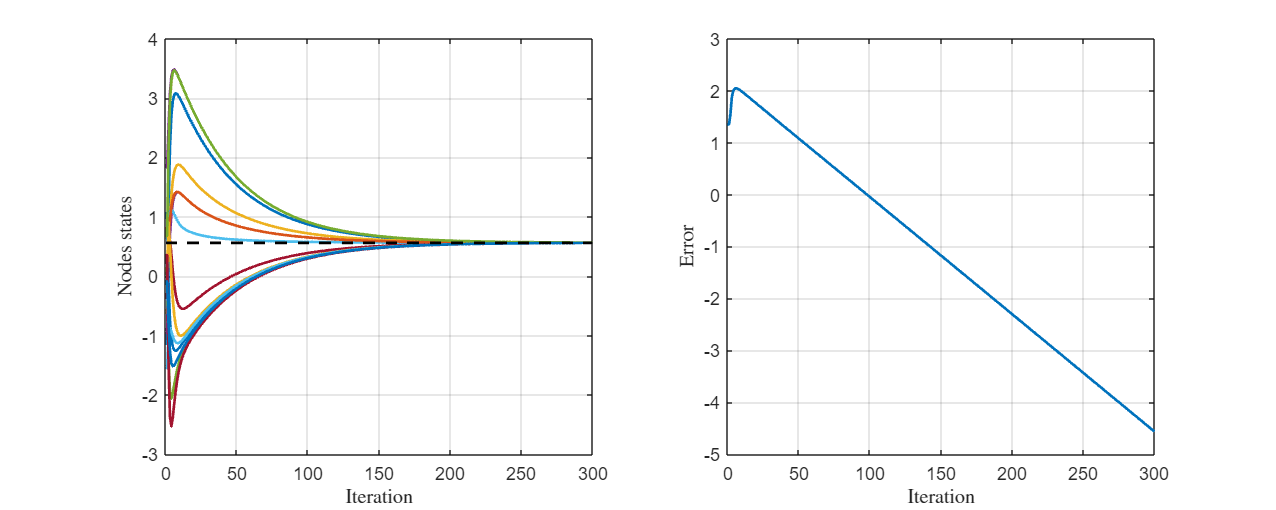

sim_len = 300; % simulations length
epsilon = 0.5;

X = [x0, x0, zeros(N,sim_len-2)]; % nodes states

% definition of g and h
g = @(x) (a.*x - 1).*a.*c.*exp(a.*x) + (b.*x + 1).*b.*d.*exp(-b.*x);
h = @(x) a.^2.*c.*exp(a.*x) + b.^2.*d.*exp(-b.*x);

% guess of sum g_i's and h_i's
Y = g(x0);
S = h(x0);

for k = 2:sim_len
    
    % update guesses of sum g_i's and h_i's
    Y = P*(Y + g(X(:, k)) - g(X(:, k-1)));
    S = P*(S + h(X(:, k)) - h(X(:, k-1)));
    
    % update states (guess of solution)
    X(:,k+1) = (1-epsilon)*X(:,k) + epsilon*Y./S;

end

% compute final x and f values
x_nr = mean(X(:, end));
fval_nr = f(x_nr);

% plot result
plot_results(X, x_opt)

## ADMM

% ADMM parameters
rho = 0.01;                   % penalty parameter
alpha = 0.5;                  % step-size
sim_len = 200;                 % simulation length

X = [x0, zeros(N,sim_len)];   % node states

% auxiliary and temporary variables
Z = zeros(N);
Q = zeros(N);

for k = 1:sim_len
    % update the states
    for i = 1:N
        
        % update x
        f_admm = @(x) c(i)*exp(a(i)*x) + d(i)*exp(-b(i)*x) - sum(Z(:,i))*x + (rho/2)*d_vec(i)*x^2;
        X(i,k+1) = fmincon(f_admm, X(i, k));
        
        % compute packets
        for j = find(A(i,:))
            Q(i,j) = -Z(j,i) + 2*rho*X(i,k+1);
        end
    end
    
    % update the auxiliary variables
    for i = 1:N
        for j = find(A(i,:))
            
            Z(j,i) = (1-alpha)*Z(j,i) + alpha*Q(j,i);
            
        end
    end 
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

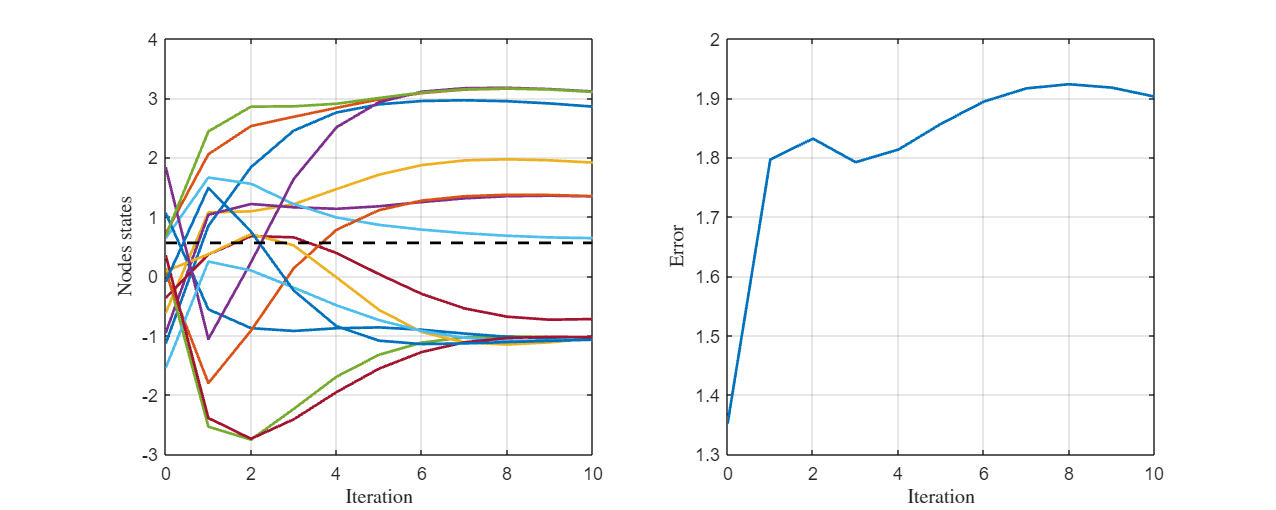

% compute final x and f values
x_admm = mean(X(:, end));
fval_admm = f(x_admm);

% plot result
plot_results(X, x_opt)

## Newton-Raphson with packet losses

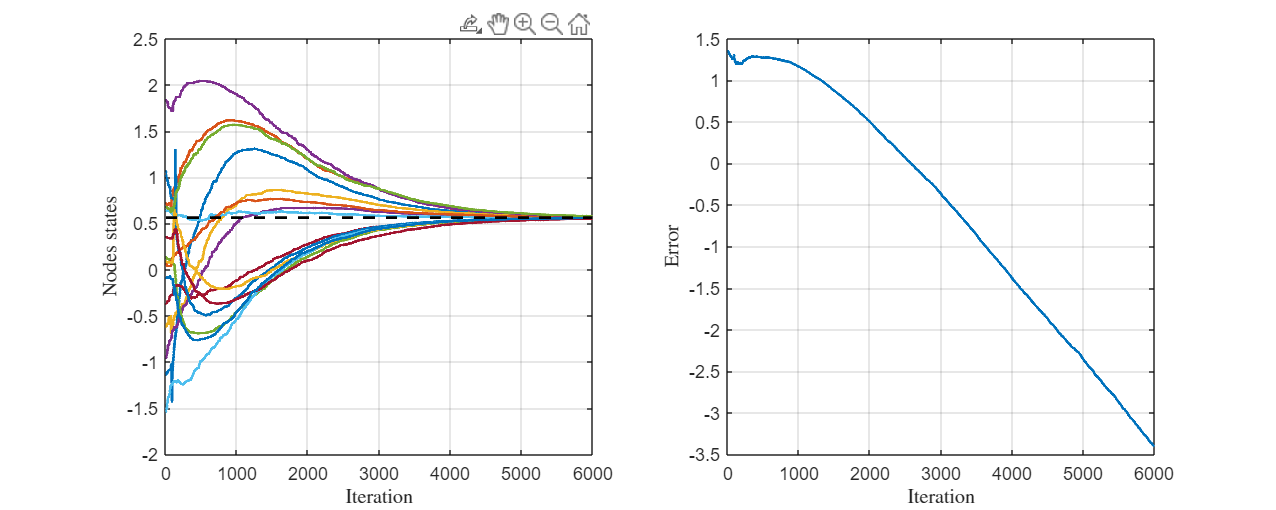

sim_len = 6000;

% packet loss probability
pl = 0.3;

% step size
epsilon = 0.01;

% node state initialization
% x0 = zeros(N, 1);
X = [x0, x0, zeros(N,sim_len-2)];

% definition of functions g and h
g = @(x, i) (a(i)*x - 1)*a(i)*c(i)*exp(a(i)*x) + (b(i)*x + 1)*b(i)*d(i)*exp(-b(i)*x);
h = @(x, i) a(i)^2*c(i)*exp(a(i)*x) + b(i)^2*d(i)*exp(-b(i)*x);

% auxiliary variables (counters of mass sent and received)
Y = zeros(N, 1);
S = ones(N, 1);
G = zeros(N,1);
G_old = zeros(N,1);
H = ones(N,1);
H_old = ones(N,1);
sigma_y = zeros(N, 1);
sigma_s = zeros(N, 1);
rho_y = zeros(N);
rho_s = zeros(N);

for k = 2:sim_len

    X(:, k+1) = X(:, k);
 
    % select random node to transmit
    i = randi(N);

    % update the auxiliary states
    Y(i) = 1/(d_vec(i)+1) * Y(i);
    S(i) = 1/(d_vec(i)+1) * S(i);

    % update the counters
    sigma_y(i) = sigma_y(i) + Y(i);
    sigma_s(i) = sigma_s(i) + S(i);

    % transmit to neighbors
    for j = find(A(i, :))
        if pl < rand % packet is not lost
            Y(j) = sigma_y(i) - rho_y(j, i) + Y(j);
            S(j) = sigma_s(i) - rho_s(j, i) + S(j);
            rho_y(j, i) = sigma_y(i);
            rho_s(j, i) = sigma_s(i);
            X(j, k+1) = (1-epsilon)*X(j,k) + epsilon*Y(j)/S(j);
            G_old(j) = G(j);
            H_old(j) = H(j);
            G(j) = g(X(j, k+1), j);
            H(j) = h(X(j, k+1), j);
            Y(j) = Y(j) + G(j) - G_old(j);
            S(j) = S(j) + H(j) - H_old(j);
        end
    end 
end

% compute final x and f values
x_nr2 = mean(X(:, end));
fval_nr2 = f(x_nr2);

% plot result
plot_results(X, x_opt)